# EXAMPLE: TP_class_ex9a

Compute equilibrium composition for a set of defined temperatures (400, 5000 K) and pressure (1.01325 bar) for an air mixture at standard conditions, and a set of 4 species is considered.

LS == {'N2', 'O2', 'O', 'NO'}

See wiki or ListSpecies() for predefined sets of species

**@author:** Alberto Cuadra Lara

                 PhD Candidate - Group Fluid Mechanics

                 Universidad Carlos III de Madrid

Last update March 30 2022

## Initialize

self = App({'N2', 'O2', 'O', 'NO'});

Loading NASA database ... OK!
NASA short database loaded from main path ... OK!


## Set initial conditions


self = set_prop(self, 'TR', 298, 'pR', 1 * 1.01325);
self.PD.S_Oxidizer = {'O2'};
self.PD.S_Inert    = {'N2'};
self.PD.proportion_inerts_O2 = 79/21;
self.PD.N_Oxidizer = 0.21;
self.PD.N_Inert    = 0.79;

## Set additional inputs (depedns of the problem selected)

self = set_prop(self, 'pP', self.PD.pR.value, 'TP', 400:100:5000); 

## Solve problem

self = SolveProblem(self, 'TP');

***********************************************************
-----------------------------------------------------------
Problem type: TP  | phi =  NaN
-----------------------------------------------------------
               |    REACTANTS    |      PRODUCTS
T [K]          |       298.0000  |      5000.0000
p [bar]        |         1.0132  |         1.0132
r [kg/m3]      |         1.1798  |         0.0588
h [kJ/kg]      |        -0.1533  |      9485.5176
e [kJ/kg]      |       -86.0348  |      7762.0224
g [kJ/kg]      |     -2051.5190  |    -46693.2285
s [kJ/(kg-K)]  |         6.8838  |        11.2357
W [g/mol]      |        28.8503  |        24.1209
(dlV/dlp)T [-] |                 |        -1.0064
(dlV/dlT)p [-] |                 |         1.0611
cp [kJ/(kg-K)] |         1.0114  |         1.5642
gamma [-]      |         1.3985  |         1.3187
sound vel [m/s]|       346.5645  |      1507.5905
-----------------------------------------------------------
REACTANTS               Xi [-]

## Display results

### Plots

Elapsed time is 2.05948 seconds


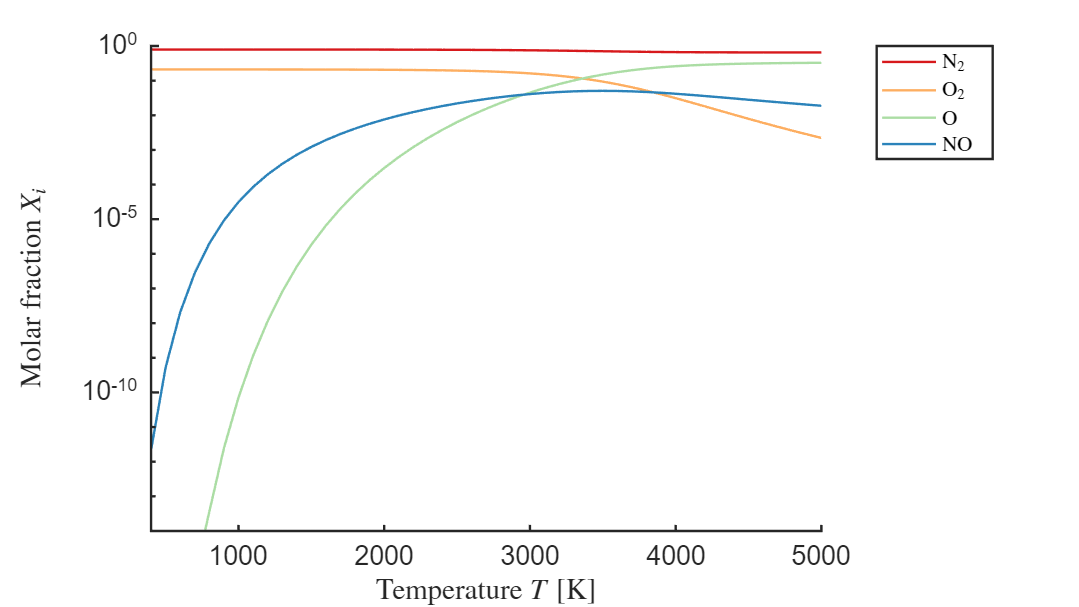

postResults(self);

### Print moles at T = 3000 K

species = self.S.LS';
mix2 = self.PS.strP;
i = find(self.PD.TP.value == 3000);
molar_fraction = mix2{i}.Xi;
moles = molar_fraction * mix2{i}.N;
table(species, moles, molar_fraction)

ans = 4×3 table
    species     moles      molar_fraction
    _______    ________    ______________

    {'N2'}      0.76904        0.75163   
    {'O2'}      0.16588        0.16213   
    {'O' }     0.046311       0.045263   
    {'NO'}     0.041922       0.040973   
